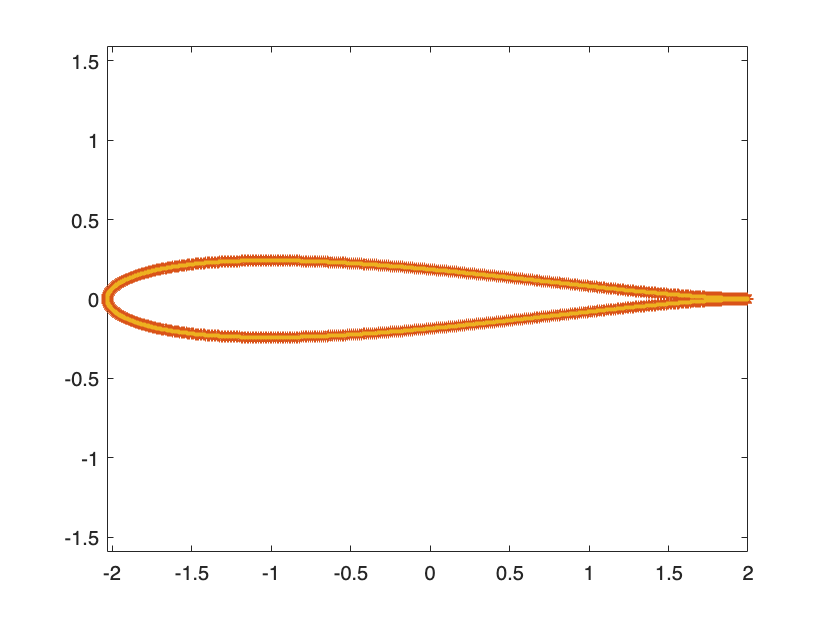

% Part 1: Define airfoil coordinates
v_inf = 1;
alpha = 15;
alpha = alpha*pi/180;
s_x = -0.102;
s_y = 0;
s = s_x + 1i*s_y;
r = sqrt((1-s_x)^2+s_y^2);

% Create points for airfoil
alpha_vec = linspace(0,2*pi,5);

for idx = 1:length(alpha_vec)
    zeta(idx) = s + r*exp(1i*alpha_vec(idx));
end

% Apply Joukowsky Transform to obtain airfoil shape
z = zeta + 1./zeta;

% Plot Airfoil
plot(real(z), -imag(z), '.', 'MarkerSize')
axis equal
l_c = max(real(z)) - min(real(z));
thickness = 100*(max(imag(z)) - min(imag(z)))/l_c;
hold on


x_pts = real(z)

x_pts =     2.0000   -0.1853   -2.0346   -0.1853    2.0000    1.9988    1.9983    1.9976    1.9969    1.9961    1.9952    1.9942    1.9931    1.9919    1.9906    1.9892    1.9877    1.9861    1.9845    1.9827    1.9808    1.9789    1.9768    1.9747    1.9724    1.9701    1.9677    1.9651    1.9625    1.9598    1.9570    1.9541    1.9511    1.9480    1.9448    1.9416    1.9382    1.9347    1.9312    1.9276    1.9238    1.9200    1.9161    1.9121    1.9080    1.9038    1.8996    1.8952    1.8908    1.8862


y_pts = -imag(z)

y_pts =          0   -0.2023   -0.0000    0.2023         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0006   -0.0007   -0.0007   -0.0008   -0.0009   -0.0010   -0.0011   -0.0012   -0.0013   -0.0014   -0.0015   -0.0017   -0.0018   -0.0019   -0.0021   -0.0022   -0.0024   -0.0026   -0.0027   -0.0029   -0.0031   -0.0033   -0.0035



for i = 1:5

% [ x1 y1 x2 y2;
%   x2 y2 x3 y3;
%   x3 y3 x4 y4]